clc;
clear;
format shortEng;

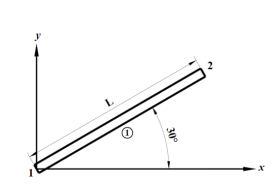

Given Data:

E=200e9;
I=0.4e-4

I =     40.0000e-006


A=1e-2;
L=4;

Calculating stiffness of the beam with reference to local coordinates

kel=[A*E/L 0 0 -A*E/L 0 0
    0 12*E*I/L^3 6*E*I/L^2 0 -12*E*I/L^3 6*E*I/L^2
    0 6*E*I/L^2 4*E*I/L 0 -6*E*I/L^2 2*E*I/L
    -A*E/L 0 0 A*E/L 0 0
    0 -12*E*I/L^3 -6*E*I/L^2 0 12*E*I/L^3 -6*E*I/L^2
    0 6*E*I/L^2 2*E*I/L 0 -6*E*I/L^2 4*E*I/L
    ]

kel =    500.0000e+006     0.0000e+000     0.0000e+000  -500.0000e+006     0.0000e+000     0.0000e+000
     0.0000e+000     1.5000e+006     3.0000e+006     0.0000e+000    -1.5000e+006     3.0000e+006
     0.0000e+000     3.0000e+006     8.0000e+006     0.0000e+000    -3.0000e+006     4.0000e+006
  -500.0000e+006     0.0000e+000     0.0000e+000   500.0000e+006     0.0000e+000     0.0000e+000
     0.0000e+000    -1.5000e+006    -3.0000e+006     0.0000e+000     1.5000e+006    -3.0000e+006
     0.0000e+000     3.0000e+006     4.0000e+006     0.0000e+000    -3.0000e+006     8.0000e+006


Calculating transformation matrix

s=30%input("Enter the angle of the beam with x axis in degrees: ")

s =     30.0000e+000


trig=[cosd(s) sind(s) 0
    -sind(s) cosd(s) 0
    0 0 1];
c=zeros(3,3);
lambda=[trig c;c trig];

Calculation of global stiffness matrix

r=lambda'*kel

r =    433.0127e+006  -750.0000e+003    -1.5000e+006  -433.0127e+006   750.0000e+003    -1.5000e+006
   250.0000e+006     1.2990e+006     2.5981e+006  -250.0000e+006    -1.2990e+006     2.5981e+006
     0.0000e+000     3.0000e+006     8.0000e+006     0.0000e+000    -3.0000e+006     4.0000e+006
  -433.0127e+006   750.0000e+003     1.5000e+006   433.0127e+006  -750.0000e+003     1.5000e+006
  -250.0000e+006    -1.2990e+006    -2.5981e+006   250.0000e+006     1.2990e+006    -2.5981e+006
     0.0000e+000     3.0000e+006     4.0000e+006     0.0000e+000    -3.0000e+006     8.0000e+006


k=r*lambda

k =    375.3750e+006   215.8568e+006    -1.5000e+006  -375.3750e+006  -215.8568e+006    -1.5000e+006
   215.8568e+006   126.1250e+006     2.5981e+006  -215.8568e+006  -126.1250e+006     2.5981e+006
    -1.5000e+006     2.5981e+006     8.0000e+006     1.5000e+006    -2.5981e+006     4.0000e+006
  -375.3750e+006  -215.8568e+006     1.5000e+006   375.3750e+006   215.8568e+006     1.5000e+006
  -215.8568e+006  -126.1250e+006    -2.5981e+006   215.8568e+006   126.1250e+006    -2.5981e+006
    -1.5000e+006     2.5981e+006     4.0000e+006     1.5000e+006    -2.5981e+006     8.0000e+006
